# Setup

close all, clear all, clc
format long, format compact
tol=1e-8;
nmax=100;
fs=16;
set(0,'defaulttextfontsize',fs);

## Excercise 1(a)

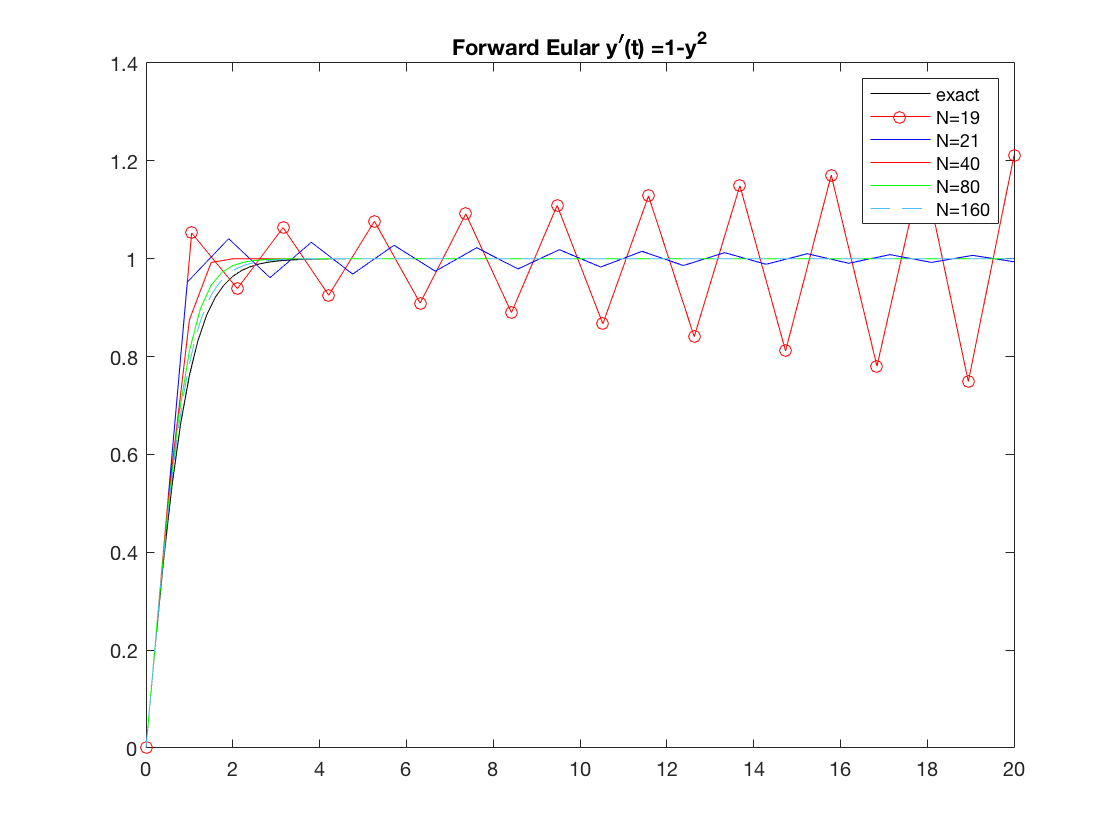

f=@(t,y)1-y.^2;
titlestring = 'y^\prime(t) =1-y^2';
y0=0;

N=[19,21,40,80,160];
tmax=20;
%h=tmax./N;

[t_fe_1, u_fe_1] = feuler(f,[0,tmax],y0,N(1));
[t_fe_2, u_fe_2] = feuler(f,[0,tmax],y0,N(2));
[t_fe_3, u_fe_3] = feuler(f,[0,tmax],y0,N(3));
[t_fe_4, u_fe_4] = feuler(f,[0,tmax],y0,N(4));
[t_fe_5, u_fe_5] = feuler(f,[0,tmax],y0,N(5));

t=tmax*(0:0.01:1);
y_ex=@(t)(exp(2*t)-1)./(exp(2*t)+1);
y=y_ex(t);

figure(1)
plot(t,y,'k')
hold on
plot(t_fe_1,u_fe_1,'ro-')
plot(t_fe_2,u_fe_2,'b')
plot(t_fe_3,u_fe_3,'r')
plot(t_fe_4,u_fe_4,'g')
plot(t_fe_5,u_fe_5,'--')
hold off

legend('exact','N=19','N=21','N=40','N=80','N=160')
title(['Forward Eular',' ',titlestring])

## compute whole errors for forward eular

e_fe_1 = max(abs(y_ex(t_fe_1) - u_fe_1));
e_fe_2 = max(abs(y_ex(t_fe_2) - u_fe_2));
e_fe_3 = max(abs(y_ex(t_fe_3) - u_fe_3));
e_fe_4 = max(abs(y_ex(t_fe_4) - u_fe_4));
e_fe_5 = max(abs(y_ex(t_fe_5) - u_fe_5));
e_fe = [e_fe_1,e_fe_2,e_fe_3,e_fe_4,e_fe_5];
A_1 = [N;e_fe];
fprintf('when N=%d global errors %d\n',A_1)

when N=19 global errors 2.698042e-01
when N=21 global errors 2.115219e-01
when N=40 global errors 1.134058e-01
when N=80 global errors 4.997661e-02
when N=160 global errors 2.396606e-02


## compute last error for forward eular

err_fe_1 = abs(u_fe_1(end)-y_ex(20));
err_fe_2 = abs(u_fe_2(end)-y_ex(20));
err_fe_3 = abs(u_fe_3(end)-y_ex(20));
err_fe_4 = abs(u_fe_4(end)-y_ex(20));
err_fe_5 = abs(u_fe_5(end)-y_ex(20));
err_fe = [err_fe_1,err_fe_2,err_fe_3,err_fe_4,err_fe_5];
A_2 = [N;err_fe];
fprintf('when N=%d last error %d\n',A_2)

when N=19 last error 2.110649e-01
when N=21 last error 6.209752e-03
when N=40 last error 0
when N=80 last error 0
when N=160 last error 2.220446e-16


## 1(b)

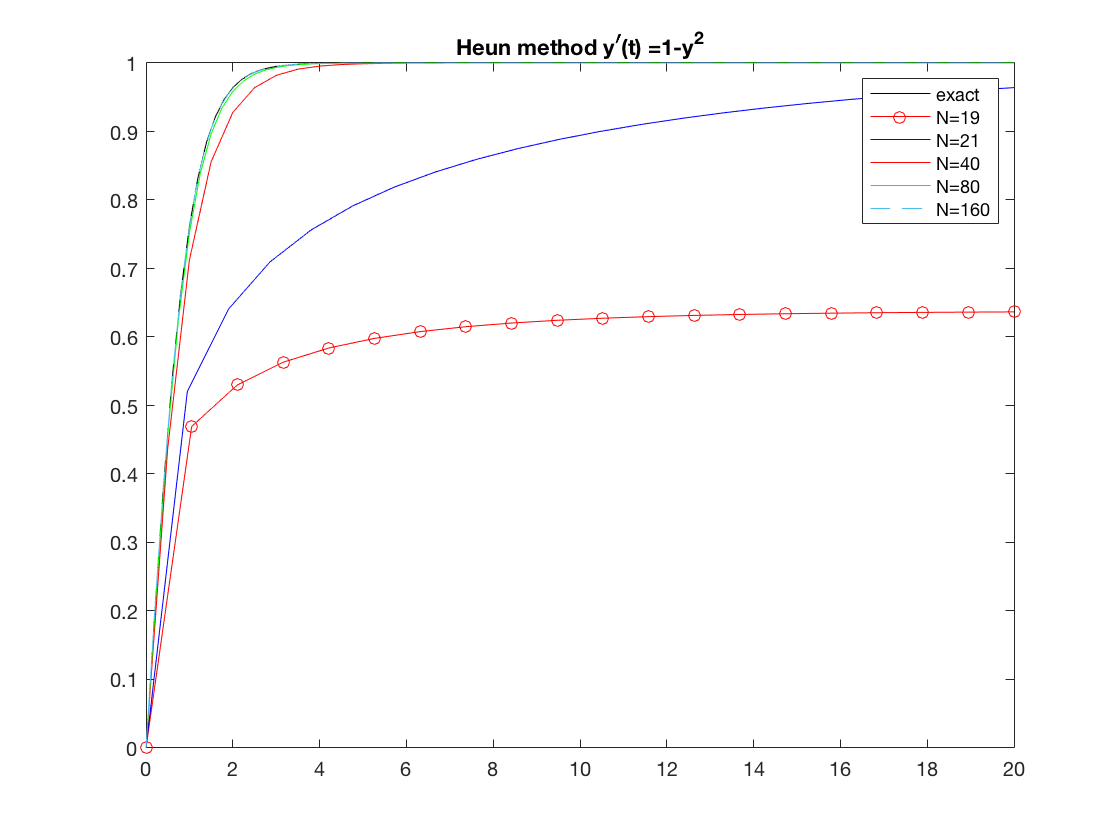

f=@(t,y)1-y.^2;
titlestring = 'y^\prime(t) =1-y^2';
y0=0;

N=[19,21,40,80,160];
tmax=20;
% h=tmax./N;
[t_hen_1, u_hen_1] = heun(f,[0,tmax],y0,N(1));
[t_hen_2, u_hen_2] = heun(f,[0,tmax],y0,N(2));
[t_hen_3, u_hen_3] = heun(f,[0,tmax],y0,N(3));
[t_hen_4, u_hen_4] = heun(f,[0,tmax],y0,N(4));
[t_hen_5, u_hen_5] = heun(f,[0,tmax],y0,N(5));

t=tmax*(0:0.01:1);
y_ex=@(t)(exp(2*t)-1)./(exp(2*t)+1);
y=y_ex(t);

figure(2)
plot(t,y,'k')
hold on
plot(t_hen_1,u_hen_1,'ro-')
plot(t_hen_2,u_hen_2,'b')
plot(t_hen_3,u_hen_3,'r')
plot(t_hen_4,u_hen_4,'g')
plot(t_hen_5,u_hen_5,'--')
hold off

legend('exact','N=19','N=21','N=40','N=80','N=160')
title(['Heun method',' ',titlestring])

## compute global error for heun

e_hen_1 = max(abs(y_ex(t_hen_1) - u_hen_1));
e_hen_2 = max(abs(y_ex(t_hen_2) - u_hen_2));
e_hen_3 = max(abs(y_ex(t_hen_3) - u_hen_3));
e_hen_4 = max(abs(y_ex(t_hen_4) - u_hen_4));
e_hen_5 = max(abs(y_ex(t_hen_5) - u_hen_5));
e_hen = [e_hen_1,e_hen_2,e_hen_3,e_hen_4,e_hen_5];
A_3 = [N;e_hen];
fprintf('when N=%d global errors %d\n',A_3)

when N=19 global errors 4.406402e-01
when N=21 global errors 3.155949e-01
when N=40 global errors 4.932883e-02
when N=80 global errors 9.671464e-03
when N=160 global errors 2.131964e-03


## compute last error for heun

err_hen_1 = abs(u_hen_1(end)-y_ex(20));
err_hen_2 = abs(u_hen_2(end)-y_ex(20));
err_hen_3 = abs(u_hen_3(end)-y_ex(20));
err_hen_4 = abs(u_hen_4(end)-y_ex(20));
err_hen_5 = abs(u_hen_5(end)-y_ex(20));
err_hen = [err_hen_1,err_hen_2,err_hen_3,err_hen_4,err_hen_5];

A_4 = [N;err_hen];
fprintf('when N=%d last error %d\n',A_4)

when N=19 last error 3.633566e-01
when N=21 last error 3.595539e-02
when N=40 last error 1.049494e-12
when N=80 last error 1.110223e-16
when N=160 last error 2.220446e-16


## 1(c)

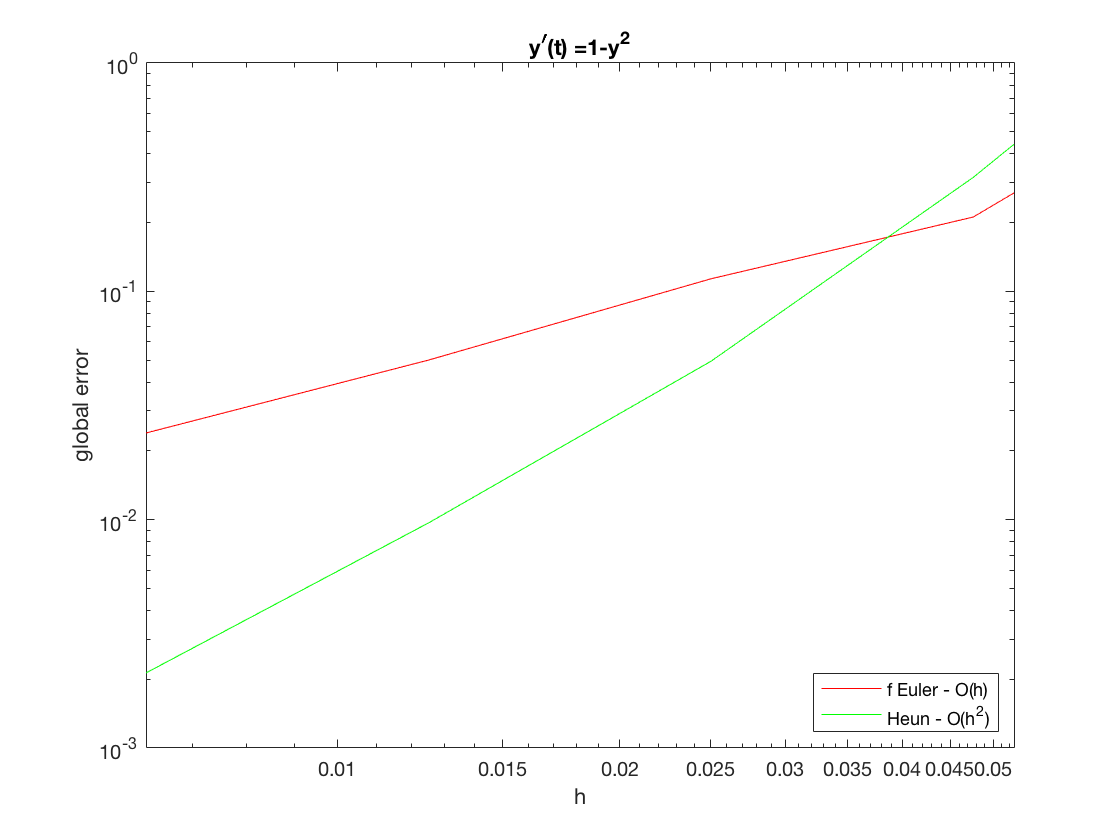

hvec=1./N;
N=[19,21,40,80,160];

figure(3)
loglog(hvec,e_fe,'r',hvec,e_hen,'g')
xlabel('h')
ylabel('global error')
legend('f Euler - O(h)','Heun - O(h^2)','Location','SouthEast')
title(titlestring)

When plotting global error, the numerical solution supports lecture theory. Forward Eular is first oder accuracy which presents slop 1 ing raph while Heun's method is second order accuracy and shows slop p=2 in figure.

## 1(d)

% plot(t,y)
fprintf('max value of feluar when N=19 %d\n',max(u_fe_1))

max value of feluar when N=19 1.211065e+00


fprintf('max value of feluar when N=20 %d\n',max(u_fe_2))

max value of feluar when N=20 1.040924e+00


fprintf('max value of heun when N=19 %d\n',max(u_hen_1))

max value of heun when N=19 6.366434e-01


fprintf('max value of heun when N=20 %d\n',max(u_hen_2))

max value of heun when N=20 9.640446e-01


fprintf('max value of heun when N=40 %d\n',max(u_hen_3))

max value of heun when N=40 1.000000e+00


1. when N>= 40,Forward Eular asymptotes to 1. Otherwise, the approximation oscillates around one. when N=19, Heun's method approximates to 0.6 rather than 1. And when N=21, the line tends to 1 in a slow speed which means y(20) still far away from 1, not a good approximation. For the rest N, the lines asymptotes to 1.

2. From lecture notes, Forward Euler needs h<1 to be stable, while Heun's method is unconditional stable. The theory is the same as I computed from the numerical solution.

3. When h>1,Forward Eular shows unstable solution and oscillates around 1. Although Heun's Method is stable, it converges to 0.6 rather than 1, the exact solution.

## 2(a)

Forward Eular: $u_{n+1}=u_n +k(-Au_n +b)$

Backward Eular:

$u_n+1 = u_n + k(-Au_{n+1} +b)$=$u_{n+1} = (I+kA)^{-1}*(u_n +kb)$

Crank-Nicoslon: :$u_{n+1} = (I+0.5k*A)^{-1}*[(I-0.5k*A)u_n + k*b]$

## 2(b)

clear all
N = 40;
h = 1/N;
k =h;
T =0.2;
x = 0:h:1;
t = 0:k:T;

A= (2/h^2)*diag(ones(N-1,1)) - (1/h^2)*diag(ones(N-2,1),1)...
 - (1/h^2)*diag(ones(N-2,1),-1);
b = ones((N-1),1);

% boundary u_n0=sin(pi x)+1/2x(1-x)
u=zeros(length(x),length(t));
u(:,1) = sin(pi.*x)+1/2*x.*(1-x);
% inital value
u(1,:)=0;
u(end,:)=0;
% exact solution
u_ex = @(x,t)exp(-pi^2*t)+1/2*x.*(1-x);

## Forward Eular

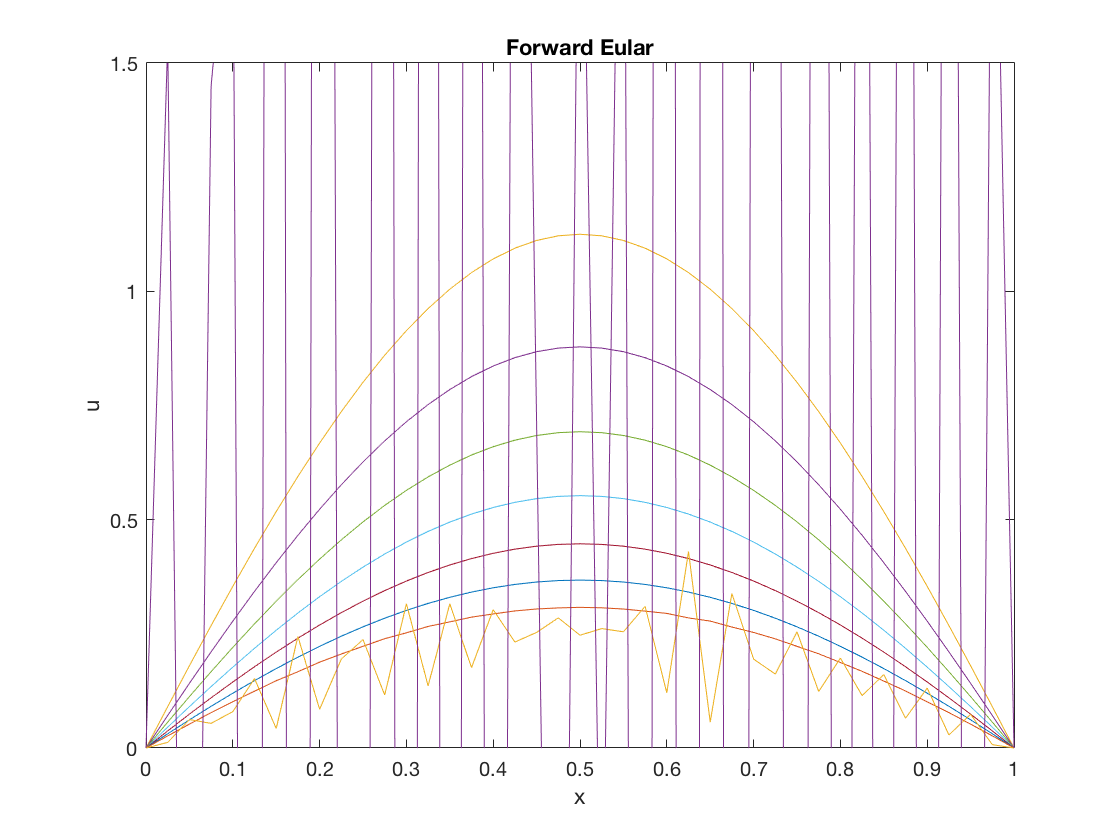

for m=1:length(t)-1
   u(2:end-1,m+1) = u(2:end-1,m)+k*(-A*u(2:end-1,m)+b);
end
figure(1)
plot(x,u)
ylim([0,1.5])
xlabel('x')
ylabel('u')
title('Forward Eular')
hold on

## Backward Eular

rearrange equation so that RHS is about u_n

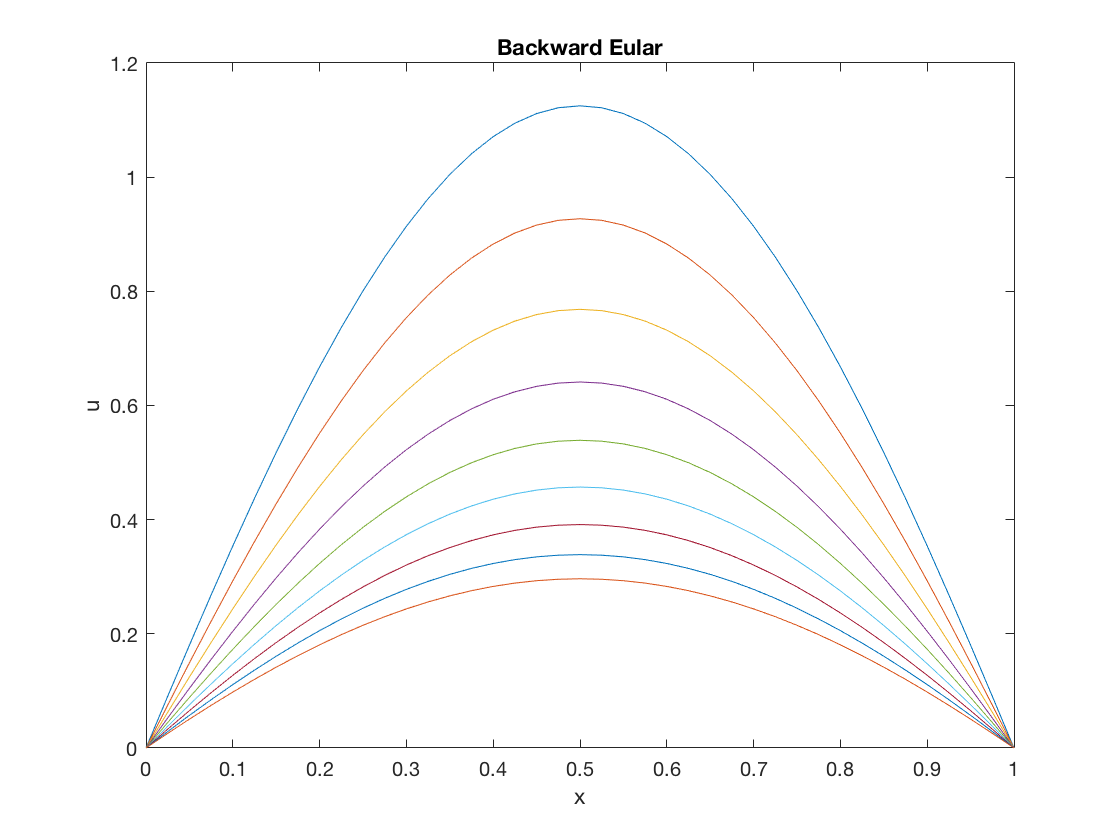

I = eye(size(A));

for m = 2:length(t)
    u(2:end-1,m) = (I+k*A)\(u(2:end-1,m-1)+k*b);
end
figure(2)
plot(x,u)
xlabel('x')
ylabel('u')
title('Backward Eular')

## Crank-Nicoslon

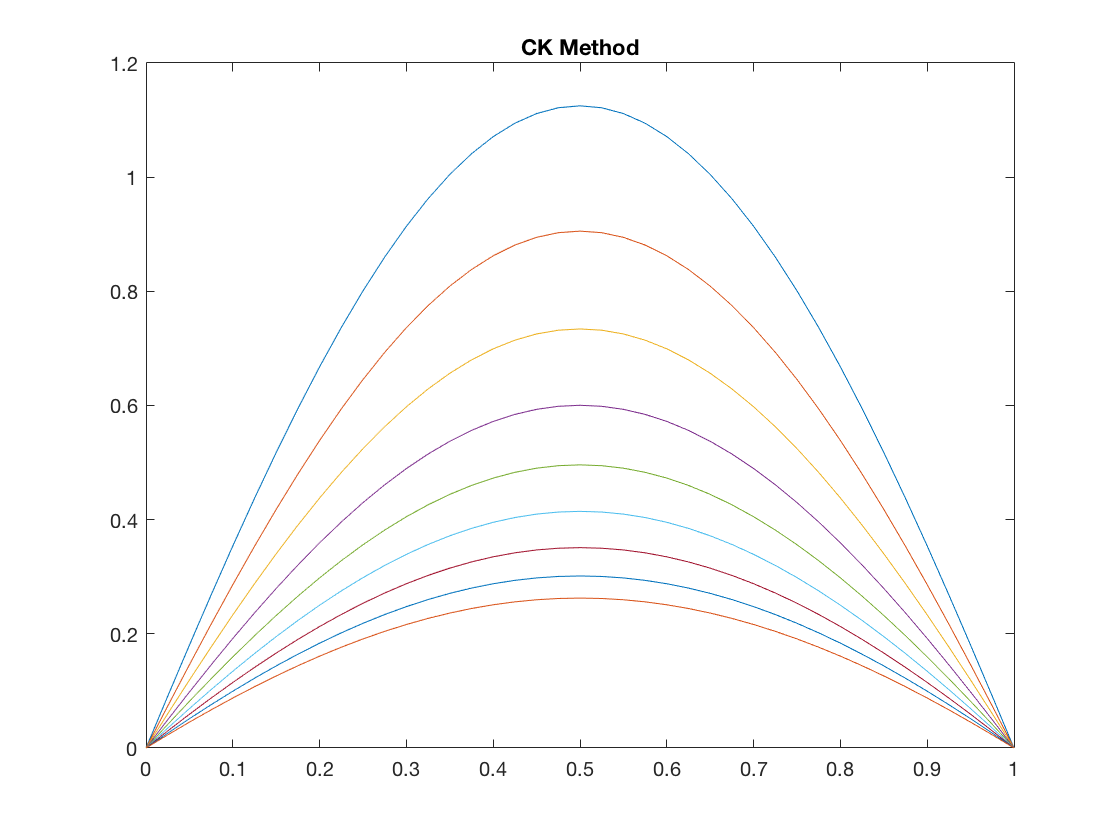

I = eye(size(A));

for m = 2:length(t)
    u(2:end-1,m) = (I+0.5*k*A)\((I-0.5*k*A)*u(2:end-1,m-1)+k*b);
end
figure(3)
plot(x,u)
title('CK Method')

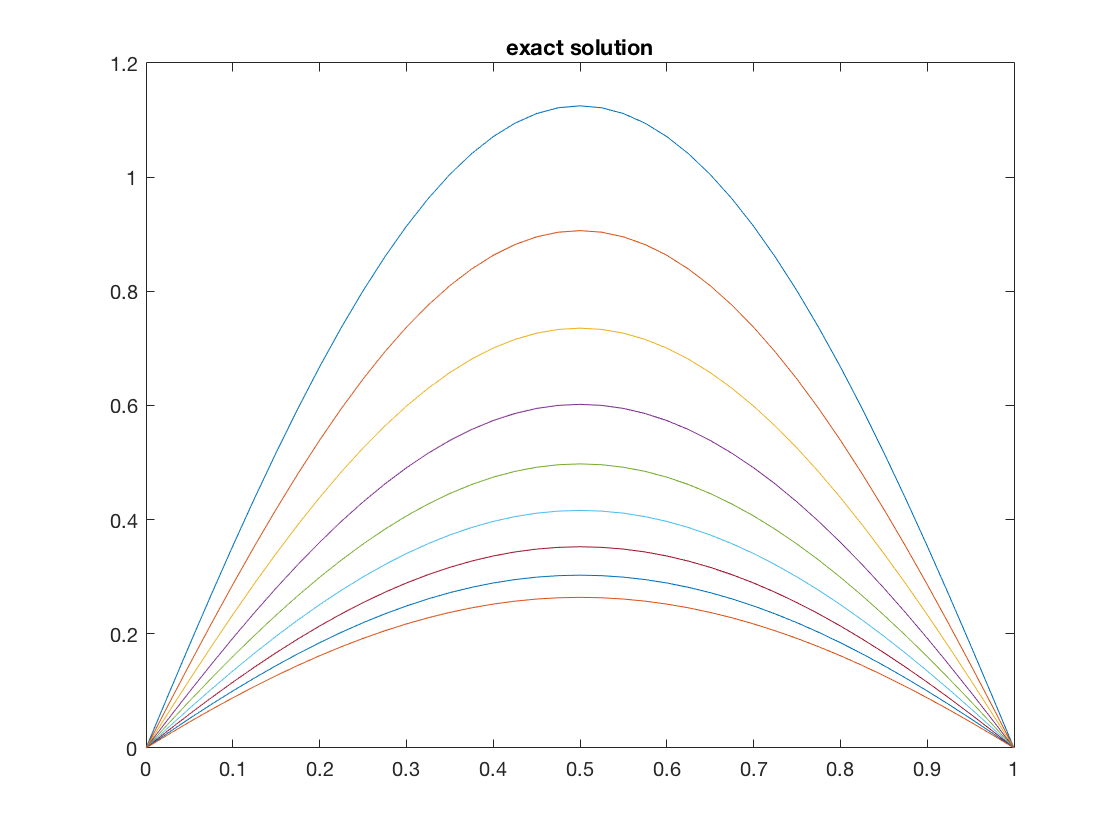

% plot exact solution
u_ex = @(x,t)exp(-pi^2*t)*sin(pi*x)+1/2*x*(1-x);

u_ex_sol = zeros(length(x),length(t));
for i = 1:length(t)
    u_x=zeros(length(x),1);
    for j = 1:length(x)
    u_x(j) = u_ex(x(j),t(i));
    end
    u_ex_sol(:,i) = u_x;
end
figure(4)
plot(x,u_ex_sol)
title('exact solution')

## （C）square root

clear all
Nvec = [10,20,40,80,160];
hvec = 1./Nvec;

% calculate exact final value
u_exact=@(x,t)exp(-pi^2*t)*sin(pi*x)+1/2*x*(1-x);
final_colomun = cell(1,5);
x_n = cell(1,5);
t = cell(1,5);
for i = 1:length(hvec)
    x_n{i} = 0:hvec(i):1;
    t{i} = 0:hvec(i):0.2;
    final = zeros(length(x_n{i}),1);   
     for j = 1:length(x_n{i})
         final(j) = u_exact(x_n{i}(j),0.2);
     end
     final_colomun{i} = final;
end

% creat 5 different u based on different step size
u = cell(1,5);
for i = 1:5
    % boundary u_n0=sin(pi x)+1/2x(1-x)
    u{i}=zeros(length(x_n{i}),length(t{i}));
    left = zeros(length(x_n{i}),1);
    for j = 1:length(x_n{i})
        left(j) = sin(pi.*x_n{i}(j))+1/2*x_n{i}(j).*(1-x_n{i}(j));
    end
    u{i}(:,1) = left;
    u{i}(1,:)=0;
    u{i}(end,:)=0;
end

% create 5 different A and b
A = cell(1,5);
b = cell(1,5);
for i = 1:5
    A{i}=(2/hvec(i)^2)*diag(ones(Nvec(i)-1,1)) - (1/hvec(i)^2)*diag(ones(Nvec(i)-2,1),1)...
 - (1/hvec(i)^2)*diag(ones(Nvec(i)-2,1),-1);
    b{i}= ones((Nvec(i)-1),1);  
end

## forward Eular

for i = 1:5
    for m = 1:length(t{i})-1
        u{i}(2:end-1,m+1) = u{i}(2:end-1,m)+ hvec(i)*(-A{i}*u{i}(2:end-1,m)+b{i});
    end
end
FE_error = zeros(1,5);
for i = 1:5
    element = (final_colomun{i}(2:end-1)-u{i}(2:end-1,end)).^2;
    FE_error(i) = sqrt(hvec(i)*sum(element));
end
FE_p = (log(FE_error(1))-log(FE_error(2)))/(log(hvec(1))-log(hvec(2)));
fprintf('slop p of Forward Eular %d\n',FE_p)

slop p of Forward Eular 9.323045e-01


## Backward Eular

for i = 1:5
    I = eye(size(A{i}));
    for m = 2:length(t{i})
        u{i}(2:end-1,m) = (I+hvec(i)*A{i})\(u{i}(2:end-1,m-1)+hvec(i)*b{i});
    end
end
BE_error = zeros(1,5);
for i = 1:5
    element = (final_colomun{i}(2:end-1)-u{i}(2:end-1,end)).^2;
    BE_error(i) = sqrt(hvec(i)*sum(element));
end
BE_p = (log(BE_error(1))-log(BE_error(2)))/(log(hvec(1))-log(hvec(2)));
fprintf('slop p of Backward Eular %d\n',BE_p)

slop p of Backward Eular 8.946704e-01


## Crank_Nicolson

for i = 1:5
    I = eye(size(A{i}));
    for m = 2:length(t{i})
        u{i}(2:end-1,m) = (I+0.5*hvec(i)*A{i})\((I-0.5*hvec(i)*A{i})*u{i}(2:end-1,m-1)+hvec(i)*b{i});
    end
end
CK_error = zeros(1,5);
for i = 1:5
    element = (final_colomun{i}(2:end-1)-u{i}(2:end-1,end)).^2;
    CK_error(i) = sqrt(hvec(i)*sum(element));
end
CK_p = (log(CK_error(1))-log(CK_error(2)))/(log(hvec(1))-log(hvec(2)));
fprintf('slop p of Crank-Nicolson %d\n',CK_p)

slop p of Crank-Nicolson 2.074513e+00


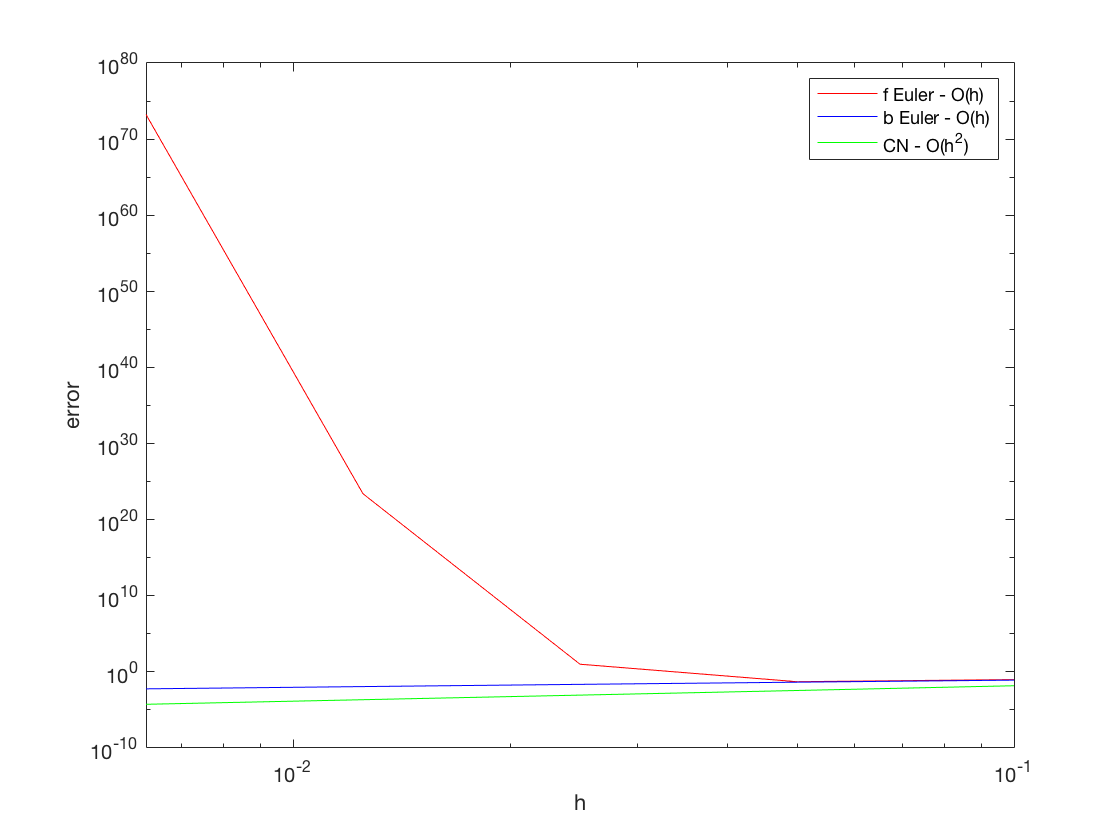

figure(4)
loglog(hvec,FE_error,'r')
hold on 
loglog(hvec,BE_error,'b')
loglog(hvec,CK_error,'g')
hold off
xlabel('h')
ylabel('error')
legend('f Euler - O(h)','b Euler - O(h)','CN - O(h^2)')

## (d) vary k and h wrong later

clear all
% to determin p
M =6400;
Nvec = [10,20,40];
k = 0.2/M;
hvec = 1./Nvec;

% calculate exact final value
u_exact=@(x,t)exp(-pi^2*t)*sin(pi*x)+1/2*x*(1-x);
final_colomun = cell(1,3);
x_n = cell(1,3);
t = 0:k:0.2;
for i = 1:length(hvec)
    x_n{i} = 0:hvec(i):1;
    final = zeros(length(x_n{i}),1);   
     for j = 1:length(x_n{i})
         final(j) = u_exact(x_n{i}(j),0.2);
     end
     final_colomun{i} = final;
end

% creat 3 different u based on different step size
u = cell(1,3);
for i = 1:3
    % boundary u_n0=sin(pi x)+1/2x(1-x)
    u{i}=zeros(length(x_n{i}),length(t));
    left = zeros(length(x_n{i}),1);
    for j = 1:length(x_n{i})
        left(j) = sin(pi.*x_n{i}(j))+1/2*x_n{i}(j).*(1-x_n{i}(j));
    end
    u{i}(:,1) = left;
    u{i}(1,:)=0;
    u{i}(end,:)=0;
end

% create 3 different A and b
A = cell(1,3);
b = cell(1,3);
for i = 1:3
    A{i}=(2/hvec(i)^2)*diag(ones(Nvec(i)-1,1)) - (1/hvec(i)^2)*diag(ones(Nvec(i)-2,1),1)...
 - (1/hvec(i)^2)*diag(ones(Nvec(i)-2,1),-1);
    b{i}= ones((Nvec(i)-1),1);  
end

## Backward Eular

for i = 1:3
    I = eye(size(A{i}));
    for m = 2:length(t)
        u{i}(2:end-1,m) = (I+k*A{i})\(u{i}(2:end-1,m-1)+k*b{i});
    end
end
BE_error = zeros(1,3);
for i = 1:3
    element = (final_colomun{i}(2:end-1)-u{i}(2:end-1,end)).^2;
    BE_error(i) = sqrt(hvec(i)*sum(element));
end

## CK

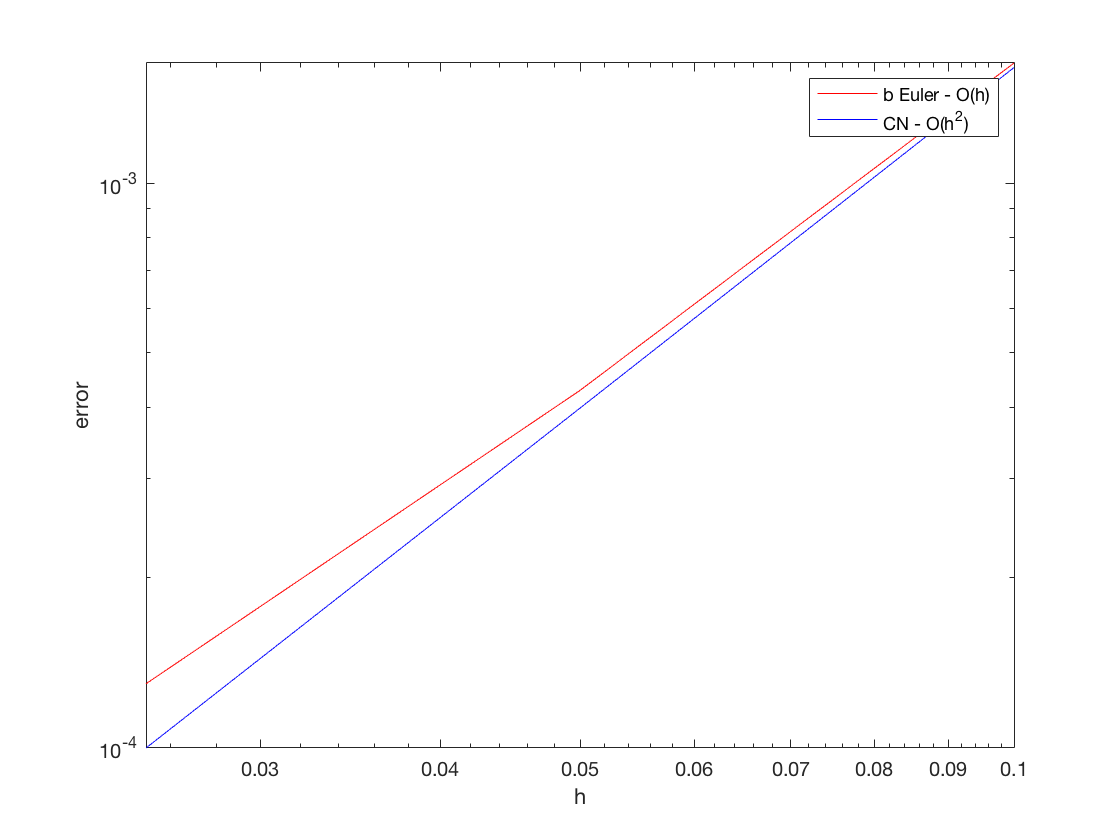

for i = 1:3
    I = eye(size(A{i}));
    for m = 2:length(t)
        u{i}(2:end-1,m) = (I+0.5*k*A{i})\((I-0.5*k*A{i})*u{i}(2:end-1,m-1)+k*b{i});
    end
end
CK_error = zeros(1,3);
for i = 1:3
    element = (final_colomun{i}(2:end-1)-u{i}(2:end-1,end)).^2;
    CK_error(i) = sqrt(hvec(i)*sum(element));
end
figure(5)
loglog(hvec,BE_error,'r')
hold on 
loglog(hvec,CK_error,'b')
hold off
xlabel('h')
ylabel('error')
legend('b Euler - O(h)','CN - O(h^2)')

## to determin q

clear all
Mvec = [8,16,32];
N = 640;
kvec = 0.2./Mvec;
h = 1/N;

% calculate exact final value
u_exact=@(x,t)exp(-pi^2*t)*sin(pi*x)+1/2*x*(1-x);
x_n = 0:h:1;
t = cell(1,3);
for i = 1:3
    t{i} = 0:kvec(i):0.2;
end

final_colomun = zeros(length(x_n),1);
for i = 1:length(x_n)
    final_colomun(i) = u_exact(x_n(i),0.2);
end

A= (2/h^2)*diag(ones(N-1,1)) - (1/h^2)*diag(ones(N-2,1),1)...
 - (1/h^2)*diag(ones(N-2,1),-1);
b = ones((N-1),1);

% creat 3 different u based on different step size
u = cell(1,3);
for i = 1:3
    u{i}=zeros(length(x_n),length(t{i}));
    for j = 1:length(x_n)
        u{i}(j,1)=sin(pi.*x_n(j))+1/2*x_n(j).*(1-x_n(j));
    end
    u{i}(1,:)=0;
    u{i}(end,:)=0;
end

## BE

I = eye(size(A));

for i = 1:3
    for m = 2:length(t{i})
        u{i}(2:end-1,m) = (I+kvec(i)*A)\(u{i}(2:end-1,m-1)+kvec(i)*b);
    end
end
BE_error = zeros(1,3);
for i = 1:3
    element = (final_colomun(2:end-1)-u{i}(2:end-1,end)).^2;
    BE_error(i) = sqrt(kvec(i)*sum(element));
end

## CK

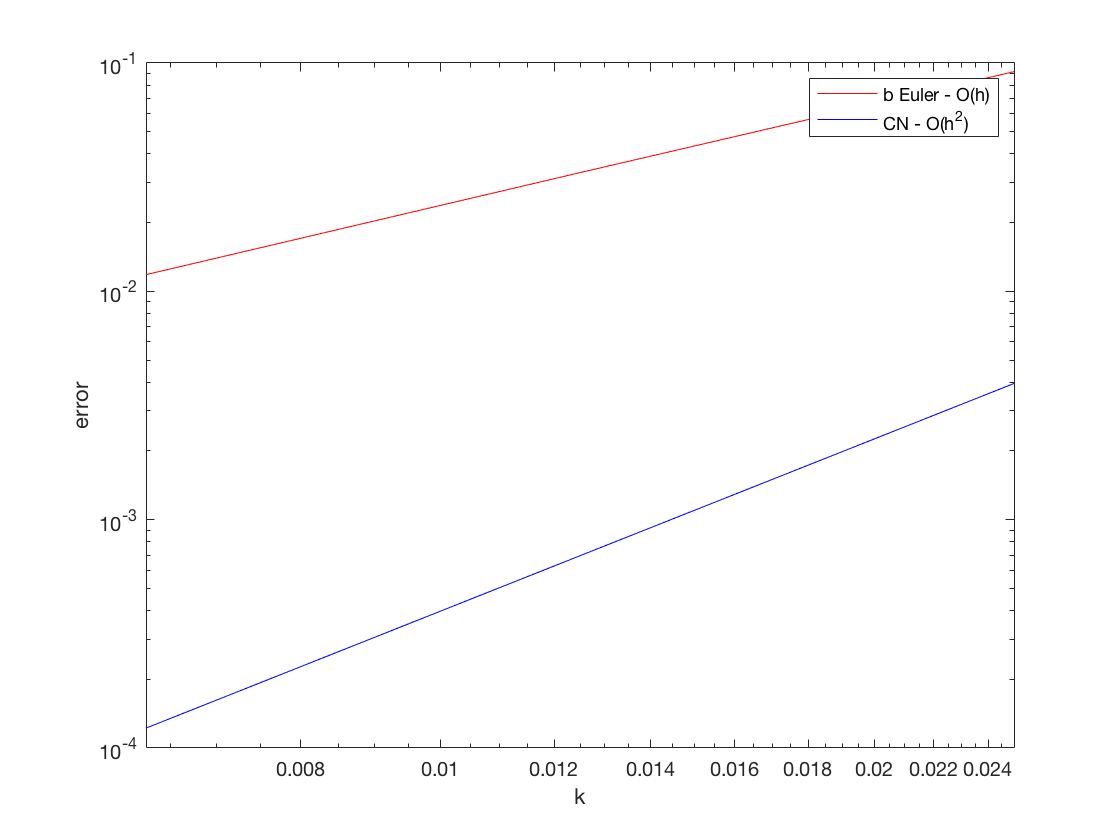

I = eye(size(A));
for i = 1:3
    for m = 2:length(t{i})
        u{i}(2:end-1,m) = (I+0.5*kvec(i)*A)\((I-0.5*kvec(i)*A)*u{i}(2:end-1,m-1)+kvec(i)*b);
    end
end
CK_error = zeros(1,3);
for i = 1:3
    element = (final_colomun(2:end-1)-u{i}(2:end-1,end)).^2;
    CK_error(i) = sqrt(kvec(i)*sum(element));
end
figure(6)
loglog(kvec,BE_error,'r')
hold on 
loglog(kvec,CK_error,'b')
hold off
xlabel('k')
ylabel('error')
legend('b Euler - O(h)','CN - O(h^2)')

## 2(e)

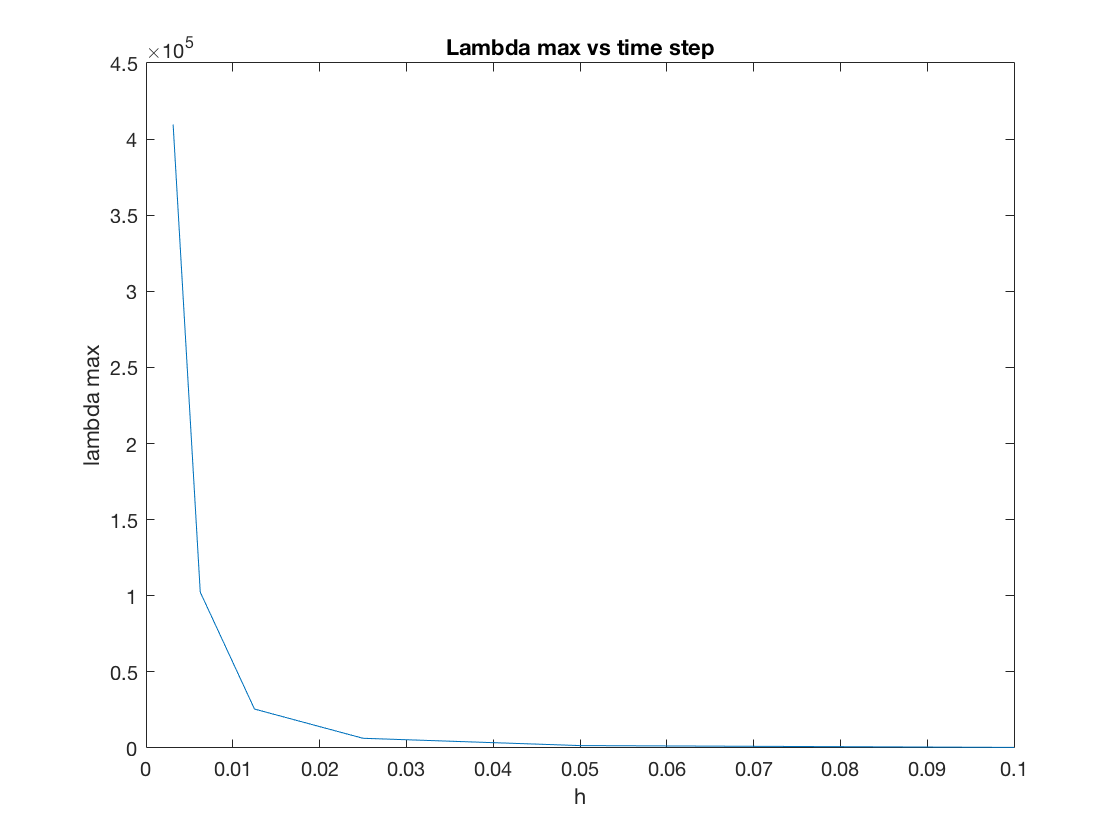

clear all
Nvec = [10,20,40,80,160,320];
hvec = 1./Nvec;
% create 6 different A and b
A = cell(1,6);
b = cell(1,6);
for i = 1:6
    A{i}=(2/hvec(i)^2)*diag(ones(Nvec(i)-1,1)) - (1/hvec(i)^2)*diag(ones(Nvec(i)-2,1),1)...
 - (1/hvec(i)^2)*diag(ones(Nvec(i)-2,1),-1);
    b{i}= ones((Nvec(i)-1),1);  
end

eigenvalue = cell(1,6);
lam_max=zeros(1,6);
lam_min=zeros(1,6);
for i = 1:6
    eigenvalue{i} = eig(A{i});
    lam_max(i)=max(eigenvalue{i});
    lam_min(i)=min(eigenvalue{i});
end
figure(7)
plot(hvec,lam_max)
xlabel('h')
ylabel('lambda max')
title('Lambda max vs time step')

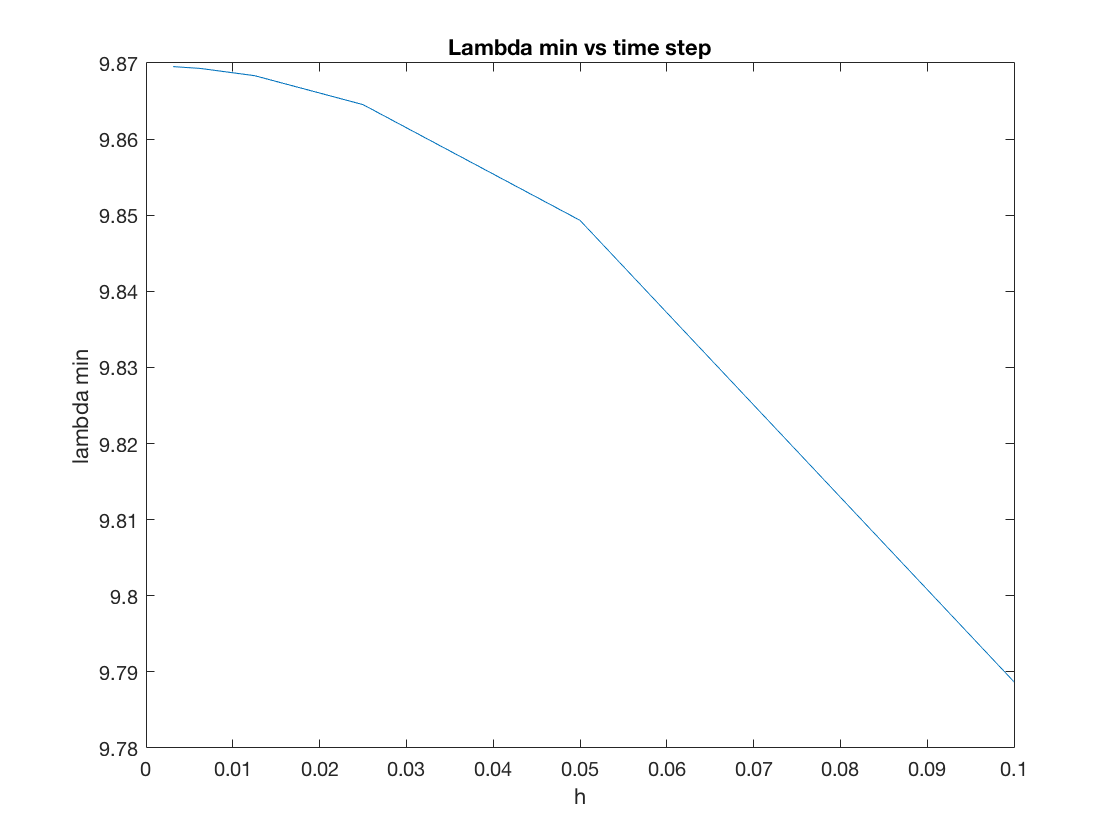


figure(8)
plot(hvec,lam_min)
xlabel('h')
ylabel('lambda min')
title('Lambda min vs time step')

From graph, it's clear that the max eigenvalues tends to infinity when h tends to 0. And we can describe such relation as $\lambda_{max}=\frac{4}{h^2}$. And the minimum eigenvalues tends to 9.86 when h tends to zero. For the forward euler method, we need to let the spectral radius of I-kA less than 1 for purpose of stable. Hence, it's equvalent to $|1-k\lambda|<1$. Hence, $k<\frac{h^2}{2},$since $\lambda_{max}=\frac{4}{h^2}$.  Therefore, c=1/2,p=2

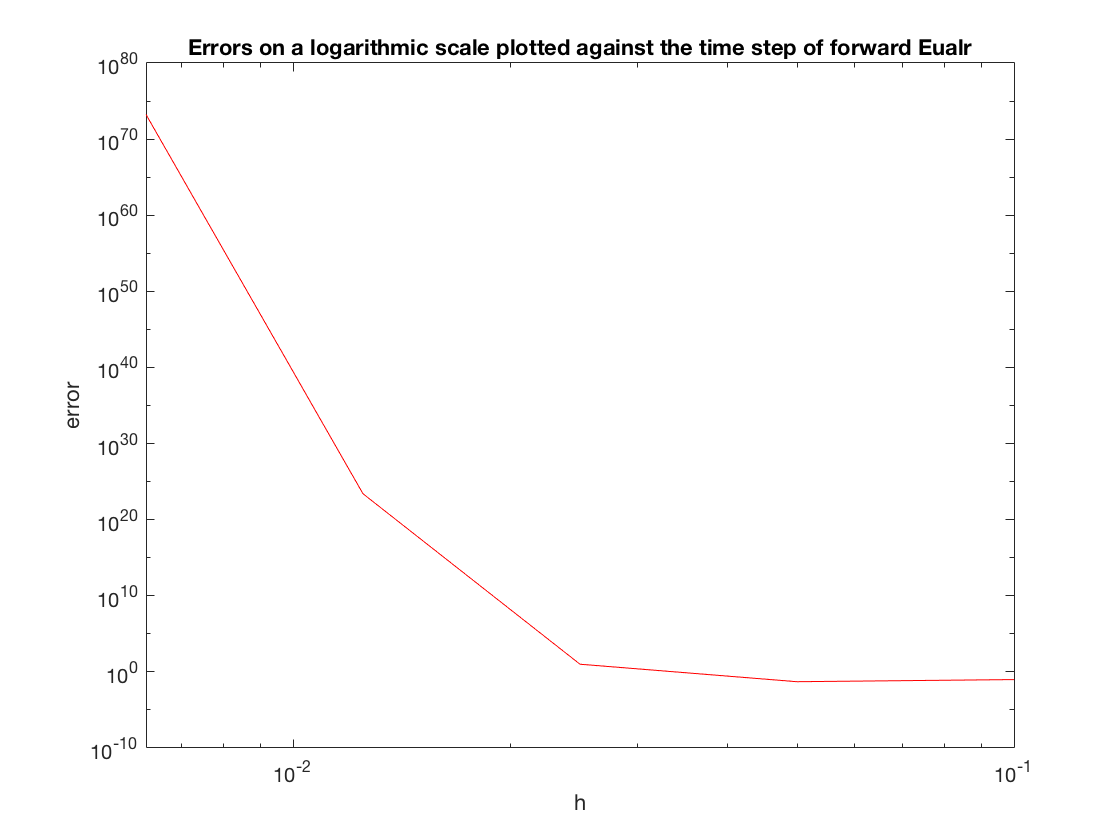

% calculate exact final value
u_exact=@(x,t)exp(-pi^2*t)*sin(pi*x)+1/2*x*(1-x);
final_colomun = cell(1,6);
x_n = cell(1,6);
t = cell(1,6);
for i = 1:length(hvec)
    x_n{i} = 0:hvec(i):1;
    t{i} = 0:hvec(i):0.2;
    final = zeros(length(x_n{i}),1);   
     for j = 1:length(x_n{i})
         final(j) = u_exact(x_n{i}(j),0.2);
     end
     final_colomun{i} = final;
end

% creat 6 different u based on different step size
u = cell(1,6);
for i = 1:6
    % boundary u_n0=sin(pi x)+1/2x(1-x)
    u{i}=zeros(length(x_n{i}),length(t{i}));
    left = zeros(length(x_n{i}),1);
    for j = 1:length(x_n{i})
        left(j) = sin(pi.*x_n{i}(j))+1/2*x_n{i}(j).*(1-x_n{i}(j));
    end
    u{i}(:,1) = left;
    u{i}(1,:)=0;
    u{i}(end,:)=0;
end

% create 6 different A and b
A = cell(1,6);
b = cell(1,6);
for i = 1:6
    A{i}=(2/hvec(i)^2)*diag(ones(Nvec(i)-1,1)) - (1/hvec(i)^2)*diag(ones(Nvec(i)-2,1),1)...
 - (1/hvec(i)^2)*diag(ones(Nvec(i)-2,1),-1);
    b{i}= ones((Nvec(i)-1),1);  
end

for i = 1:6
    for m = 1:length(t{i})-1
        u{i}(2:end-1,m+1) = u{i}(2:end-1,m)+ hvec(i)*(-A{i}*u{i}(2:end-1,m)+b{i});
    end
end
FE_error = zeros(1,6);
for i = 1:6
    element = (final_colomun{i}(2:end-1)-u{i}(2:end-1,end)).^2;
    FE_error(i) = sqrt(hvec(i)*sum(element));
end
figure(9)
hvec = 1./Nvec;
loglog(hvec,FE_error,'r')
xlabel('h')
ylabel('error')
title('Errors on a logarithmic scale plotted against the time step of forward Eualr')